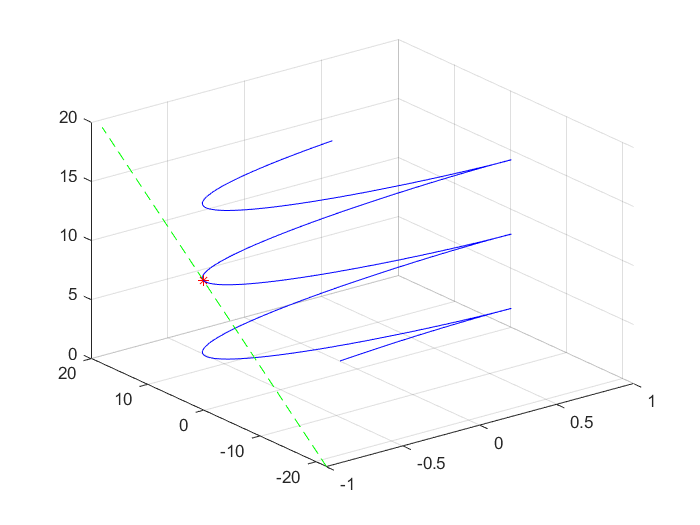

%% 0_1
t = (0:0.05:6*pi);
x = sin(t);
y = 3*cos(t);
plot3(x, y, t,'b');
hold on;
line([-1,-1], [-7*pi, (40-7*pi)], [0, 20], 'LineStyle', '--', 'Color', 'g');
plot3(-1, 0, 7*pi/2, 'r*');
hold off;
grid on;

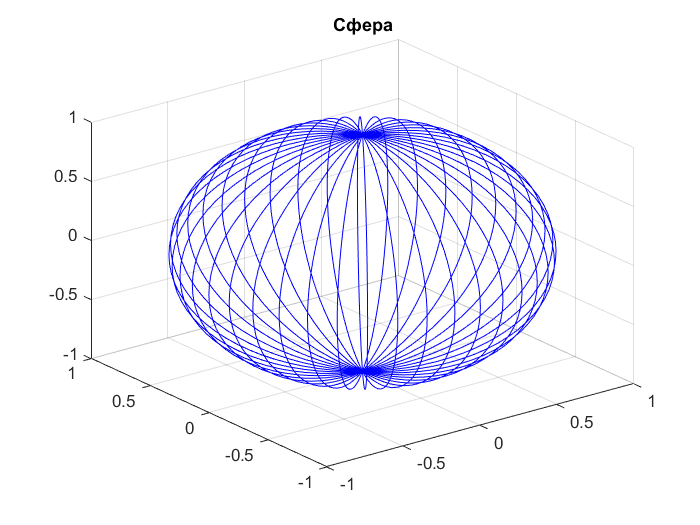

%% 0_2
n = 100;
t1 = pi*(-n:5:n)/n;
t2 = (pi/2)*(-n:5:n)'/n;
X = cos(t2)*cos(t1);
Y = cos(t2)*sin(t1);
E = ones(size(t1));
Z = sin(t2)*E;
plot3(X, Y, Z, 'b');
grid on;
title('Сфера');

%%1
XY=[-10, 10, -10, 10]

XY =    -10    10   -10    10


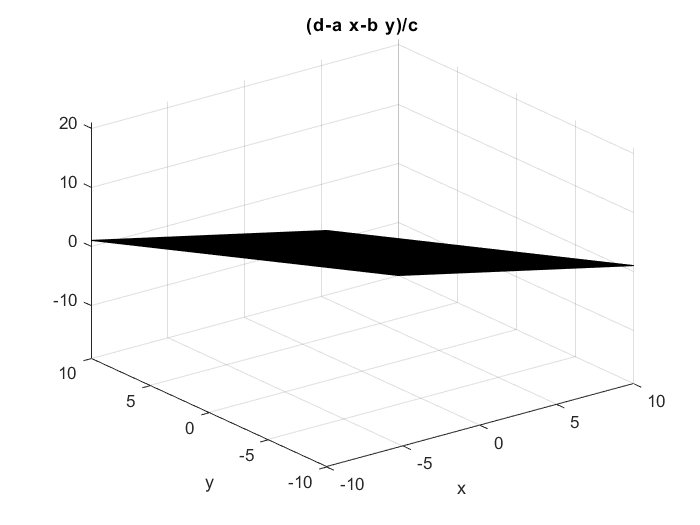

a = input("a = ");
b = input("b = ");
c = input("c = ");
d = input("d = ");
F=@(x,y)(d - a.*x - b.*y)./c ;
C=ezsurf(F,XY);

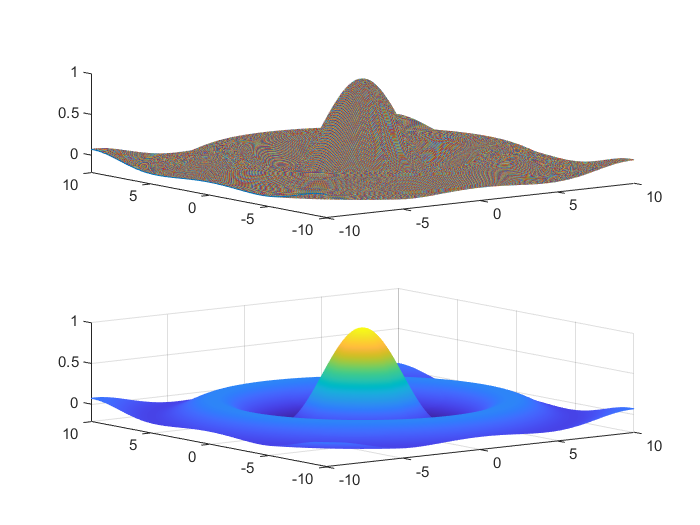

%% 2_a
x = -10:0.01:10;
y = -10:0.01:10;
a = 1;
[X, Y] = meshgrid(x,y);
Z = a*sin(sqrt(X.^2+Y.^2))./sqrt(X.^2+Y.^2);
subplot(2, 1, 1);
plot3(X, Y, Z);
subplot(2, 1, 2);
mesh(X, Y, Z);

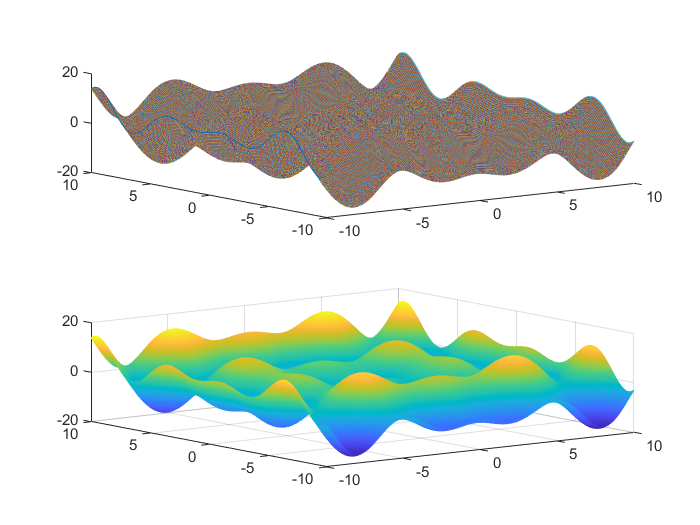

%% 2_b
x = -10:0.01:10;
y = -10:0.01:10;
[X, Y] = meshgrid(x,y);
W = -X.*sin(X)-Y.*cos(Y);
subplot(2, 1, 1);
plot3(X, Y, W);
subplot(2, 1, 2);
mesh(X,Y,W);

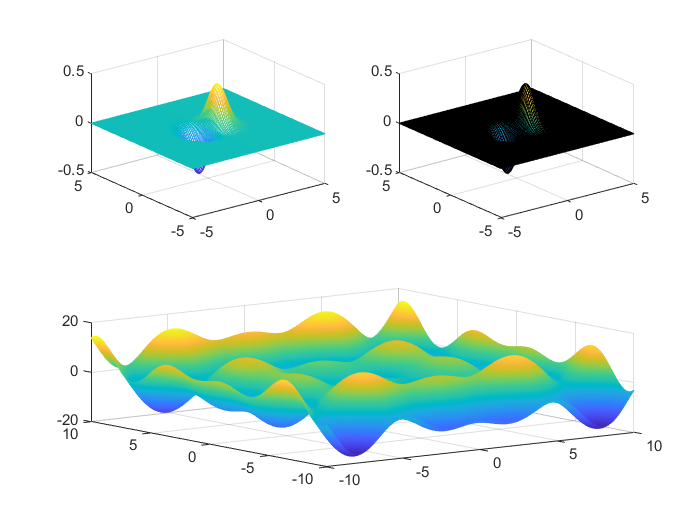

%%3_a
x = -5:0.1:5;
y = -5:0.1:5;
a = 1;
[X, Y] = meshgrid(x,y);
Z = a.*X.*exp(1).^(-X.^2-Y.^2);
subplot(2, 2, 1);
mesh(X, Y, Z);
subplot(2, 2, 2);
surf(X, Y, Z);

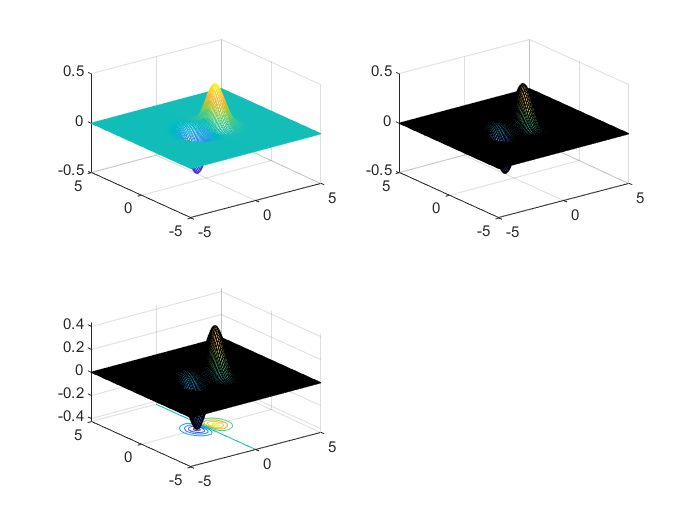

subplot(2, 2, 3);
surfc(X, Y, Z);

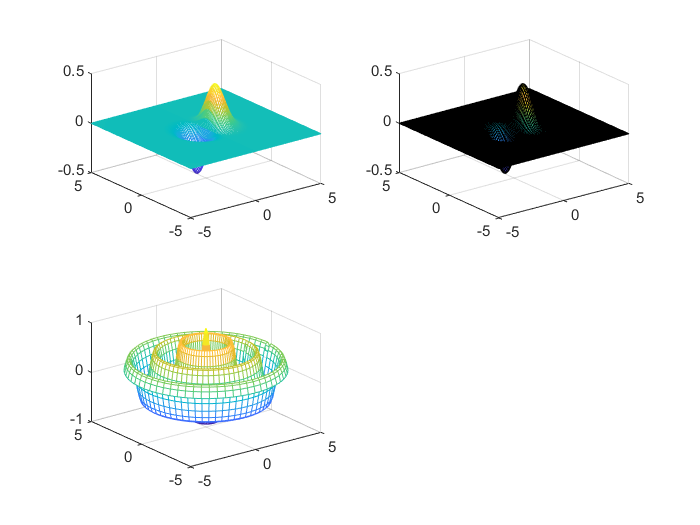

%%3_i
a=1;
m=0.2;
w=4;
phi=pi/2;
r = 0:0.1:5;
u = 0:0.1:2*pi;
[R,U] = meshgrid(r,u);
X = R.*cos(U);
Y = R.*sin(U);
Z = a.*exp(1).^(-m.*R).*sin(w.*R + phi);
mesh(X, Y, Z);

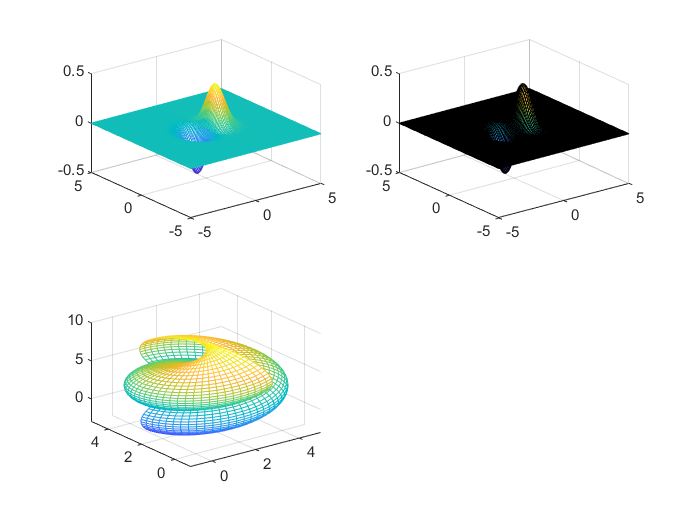

%%3_m
R=3;
a=2;
b=1;
phi = 0:0.1:2*pi;
v = 0:0.1:5;
[PHI, V] = meshgrid(phi, v);
X = (a + R.*sin(PHI).*cos(V));
Y = (a + R.*sin(PHI).*sin(V));
Z = R.*cos(PHI) + b.*V;
mesh(X, Y, Z);

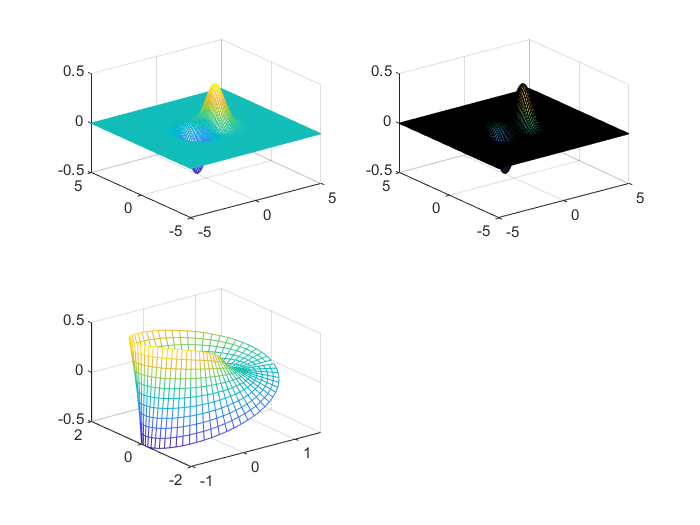

%%3_n
u = 0:0.1:2*pi;
v = -1/2:0.1:1/2;
[U, V] = meshgrid(u, v);
X = (1+V.*cos(U./2)).*cos(U);
Y = (1+V.*cos(U./2)).*sin(U);
Z = V.*sin(U./2);
mesh(X, Y, Z);